clear all

syms cc
taylor(exp(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}+\frac{{\mathrm{cc}}^{4}}{24}+\frac{{\mathrm{cc}}^{3}}{6}+\frac{{\mathrm{cc}}^{2}}{2}+\mathrm{cc}+1$$

taylor(sin(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{120}-\frac{{\mathrm{cc}}^{3}}{6}+\mathrm{cc}$$


taylor(exp(cc)) + taylor(sin(cc))+3*taylor(cos(cc))

$$ans = \frac{{\mathrm{cc}}^{5}}{60}+\frac{{\mathrm{cc}}^{4}}{6}-{\mathrm{cc}}^{2}+2\,\mathrm{cc}+4$$

input = 2*rand(1000,1)-1;
output = sin(exp(input)+sin(10*input).^2+3*cos(3*input)+0.3*rand(1000,1));

% output= (output-mean(output))/std(output);

output = normalize(output)

output =    -0.8533
   -1.1026
    1.5358
   -1.1271
   -0.8542
   -1.1606
    0.2978
    0.8599
   -0.5971
   -0.1223



datasize = length(input);
batchsize = 100;
minis = datasize/batchsize

minis = 10

decay =0.999999

decay = 1.0000

alpha = 0.00001

alpha = 1.0000e-05

alfa = 0.0001

alfa = 1.0000e-04

beta= 0

beta = 0

n=5

n = 5


V=zeros(batchsize,1) %momentum

V =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


B = 0.9

B = 0.9000

V1=0;
V2=0;
V3=0;

X = normalize(rand(n+1,4))/10;
ex= [0:n];

w1= X(:,1);
w2= X(:,2);
w3= X(:,3);

err(1)=1;


% number of epochs
for i = 2:5000

%divide data in batches
indexes= randperm(1000);
batchinput = reshape(input(indexes), [batchsize minis]);    
batchoutput = reshape(output(indexes), [batchsize minis]);

    for j = 1:minis
a1 = batchinput(:,j);
a2 = a1.^ex*w1;
a3 = a2.^ex*w2;
% a4 = a3.^ex*w3;

% d4 = a4-batchoutput(:,j);
% d3 = d4 .* [zeros(batchsize,1) ones(batchsize,1) 2*a3 3*a3.^2 4*a3.^3] *w3;
d3 = a3-batchoutput(:,j);
grad2 = gradidi(a2,n);
grad1 = gradidi(a1,n);
d2 = d3 .* grad2 *w2;
d1 = d2 .* grad1 *w1;

% D = [d2;d1]

V3=B*V3 + (1-B)*d3;
V2=B*V2 + (1-B)*d2;
V1=B*V1 + (1-B)*d1;

% w3 = pinv((a3-beta*alpha*d3).^ex)*(a4-alpha*d4)*decay;
w2 = pinv((a2-beta*alpha*V2).^ex)*(a3-alpha*(V3))*decay;
w1 = pinv((a1).^ex)*(a2-alpha*(V2))*decay;

    end

a1=input;
a2 = a1.^ex*w1;
a3 = a2.^ex*w2;
    
err(i) = norm(a3-output)/norm(output);

alpha=alfa/err(i)^2;  
alphas(i)=alpha;

if (err(i)<0.0001) ||(abs(err(i)-err(i-1))<0.0000001)
    disp("iterations: " + i)
     disp("error: " + err(i))
    break;
end
    
end

iterations: 2476


error: 0.29403



disp("error: " + err(i))

error: 0.29403


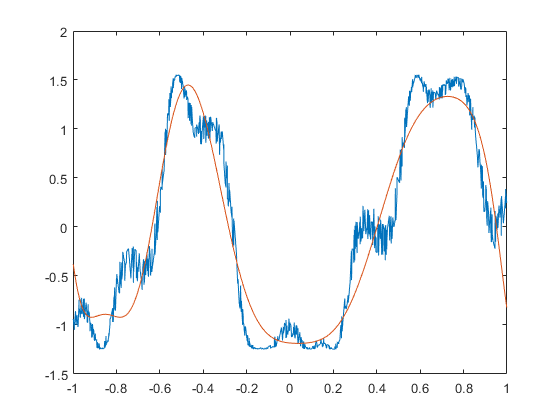

% a1=input;
% % ---------
% a2 = a1.^ex*w1;
% a3 = a2.^ex*w2;

% C = 0.5*(a3-output).^2;
% norm(a3-output)/norm(output)


[B1,I] = sort(input);
B2 = output(I);

plot([B1 B1],[B2 a3(I)])

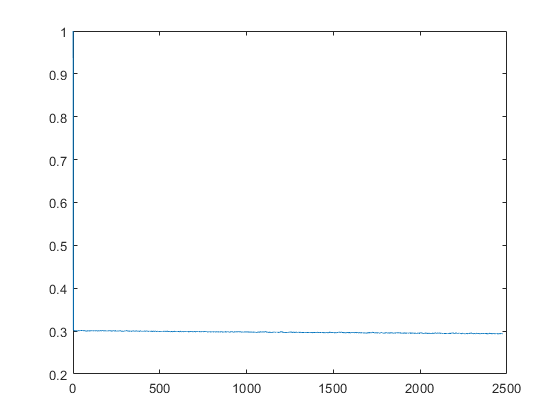


plot(err(1:i))

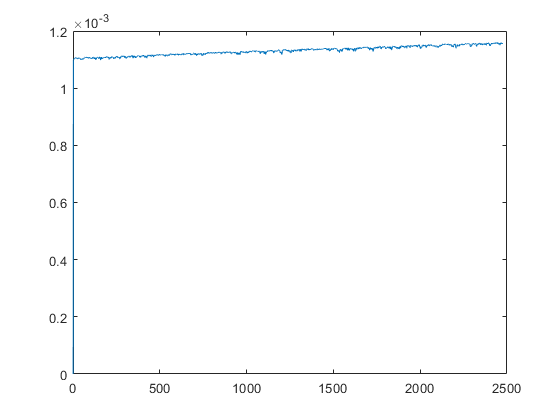

plot(alphas(1:i))


w1

w1 =    -0.1801
   -0.0719
    0.9975
   -0.1997
   -0.7843
    0.1022


w2

w2 = 	1.0e+03 *

    0.0012
    0.0101
   -0.0788
   -0.2451
    0.7722
    1.1784


% w3




ex=0:3

ex =      0     1     2     3


% zeros(1000,1) ones(1000,1)

w1 =  rand(4,1)

w1 =     0.9405
    0.2380
    0.6750
    0.7154


w2 =  rand(4,1)

w2 =     0.2634
    0.0196
    0.0665
    0.1783



a1 = input(1:200)

a1 =    -0.9340
   -0.1950
    0.7658
   -0.0158
   -0.9299
   -0.1958
    0.8895
   -0.3879
   -0.2277
    0.3586



a2 = a1.^ex*w1 

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.


a3 = a2.^ex*w2


d3 = a3-output(1:200)
d2 = d3 .* [zeros(200,1) ones(200,1) 2*a2 3*a2.^2] *w2
d1 = d3 .* [zeros(200,1) ones(200,1) 2*a1 3*a1.^2] *w1

w2 = pinv([a2-0.01*d2].^ex)*[a3-0.1*d3]*0.999
w1 = pinv(a1.^ex)*[a2-0.01*d2]*0.999

% ---------
a2 = a1.^ex*w1;

a3 = a2.^ex*w2;

C = 0.5*(a3-output(1:200)).^2;
norm(C)/norm(output(1:200))



[B1,I] = sort(input(1:200));
B2 = output(I);

plot([B1 B1],[B2 a3(I)])

w1
w2


ex= 0:10

ex =      0     1     2     3     4     5     6     7     8     9    10


input.^ex

ans =     1.0000   -0.9340    0.8724   -0.8149    0.7611   -0.7109    0.6640   -0.6202    0.5793   -0.5411    0.5054
    1.0000   -0.1950    0.0380   -0.0074    0.0014   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000
    1.0000    0.7658    0.5865    0.4491    0.3440    0.2634    0.2017    0.1545    0.1183    0.0906    0.0694
    1.0000   -0.0158    0.0003   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
    1.0000   -0.9299    0.8648   -0.8042    0.7478   -0.6954    0.6467   -0.6013    0.5592   -0.5200    0.4836
    1.0000   -0.1958    0.0383   -0.0075    0.0015   -0.0003    0.0001   -0.0000    0.0000   -0.0000    0.0000
    1.0000    0.8895    0.7913    0.7039    0.6262    0.5570    0.4955    0.4407    0.3921    0.3488    0.3102
    1.0000   -0.3879    0.1505   -0.0584    0.0226   -0.0088    0.0034   -0.0013    0.0005   -0.0002    0.0001
    1.0000   -0.2277    0.0519   -0.0118    0.0027   -0.0006    0.0001   -0.0000    0.0000   -0.0000    0.

www = pinv(input.^ex)*(output);
output

output =    -0.8533
   -1.1026
    1.5358
   -1.1271
   -0.8542
   -1.1606
    0.2978
    0.8599
   -0.5971
   -0.1223



[B1,I] = sort(input);
B2 = output(I);

recon = input.^ex*www

recon =    -0.8062
   -0.6591
    1.5687
   -1.4532
   -0.8143
   -0.6532
    0.4361
    0.9587
   -0.3851
   -0.1905


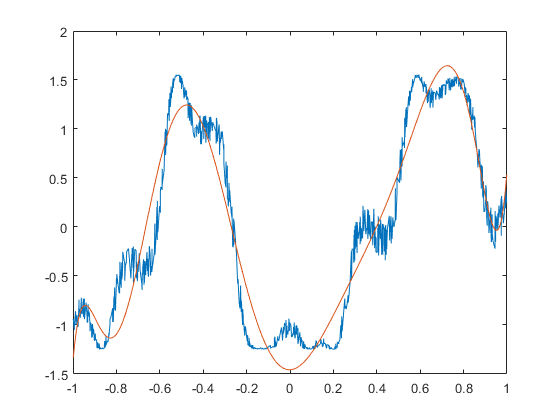


plot([B1 B1],[B2 recon(I)])


rataa = norm(recon-output)/norm(output)

rataa = 0.2864